clear;
clc;
% Number of random points to generate
numPoints = 3000;

% Generate random points
x = rand(1, numPoints);
y = rand(1, numPoints);
z = 1 - x - y;

% Ensure that points are within the specified range [0, 1]
validPoints = (x >= 0 & x <= 1) & (y >= 0 & y <= 1) & (z >= 0 & z <= 1);
x = x(validPoints);
y = y(validPoints);
z = z(validPoints);

% Store the x, y, and z coordinates in arrays
coordinates = [x; y; z]';

% Initialize arrays for vector field and transformed values
vector_field_result = zeros(size(coordinates, 1), 3);
vectorxy_field_result = zeros(size(coordinates, 1), 2);
transformed_vector_values = zeros(size(coordinates, 1), 3);
new_coordinates=zeros(size(coordinates, 1), 3);% Store x, y, z
newxy_coordinates=zeros(size(coordinates, 1), 2);
% Calculate vector field values and transform values for each point in coordinates
for i = 1:size(coordinates, 1)
    x_i = coordinates(i, 1);
    y_i = coordinates(i, 2);
    z_i = coordinates(i, 3);

    % Call your vector_field function with the x, y, and z coordinates
    vector_field_result(i,:) = vector_field(x_i, y_i, z_i);
    vector_field_result_in_barycentric(i,:)=cartesian_to_barycentric(vector_field_result(i,:));
    vectorxy_field_result(i,:)=barycentric_to_cartesian(vector_field_result_in_barycentric(i,:));
    new_coordinates(i,:)=cartesian_to_barycentric(coordinates(i,:));
    newxy_coordinates(i,:)=(barycentric_to_cartesian(new_coordinates(i,:)));

end

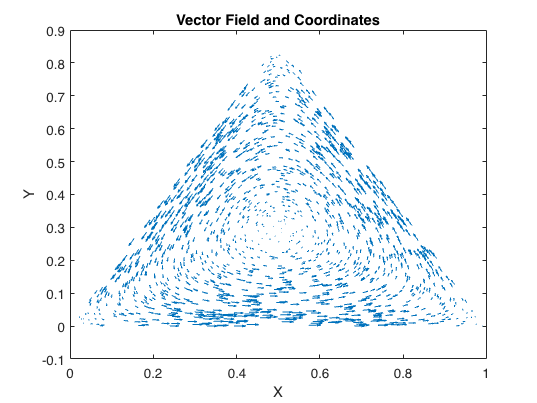


% Plot x and y coordinates along with the vector field result for x and y
x_coords = newxy_coordinates(:, 1);
y_coords = newxy_coordinates(:, 2);
u = vectorxy_field_result(:, 1); % x-component of the vector field
v = vectorxy_field_result(:, 2); % y-component of the vector field

% Create a quiver plot to visualize the vector field
quiver(x_coords, y_coords, u, v);
xlabel('X');
ylabel('Y');
title('Vector Field and Coordinates');

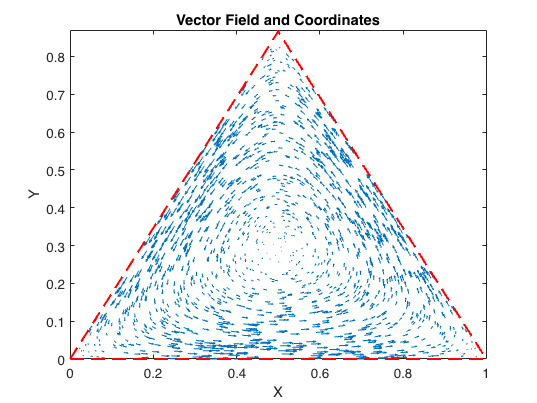

% Plot x and y coordinates along with the vector field result for x and y
x_coords = newxy_coordinates(:, 1);
y_coords = newxy_coordinates(:, 2);
u = vectorxy_field_result(:, 1); % x-component of the vector field
v = vectorxy_field_result(:, 2); % y-component of the vector field

% Create a quiver plot to visualize the vector field
quiver(x_coords, y_coords, u, v);
xlabel('X');
ylabel('Y');
title('Vector Field and Coordinates');

xlim([0, 1]);
ylim([0, sqrt(3)/2]);

% Add lines to the plot
hold on;  % Use "hold on" to overlay the lines on the existing plot

% Add lines y = 0, y = sqrt(3)/2 * x, and y = -sqrt(3)/2 * x + 1
x_values = linspace(0, 1, 100);  % Generate x values for the lines
plot(x_values, zeros(size(x_values)), 'r--', 'LineWidth', 1.5);  % y = 0 (Red dashed line)
plot(x_values, (sqrt(3)) * x_values, 'r--', 'LineWidth', 1.5);  % y = sqrt(3)/2 * x (Green dashed line)
plot(x_values, -(sqrt(3)) * x_values + sqrt(3), 'r--', 'LineWidth', 1.5);  % y = -sqrt(3)/2 * x + 1 (Blue dashed line)

hold off;  % Release the "hold on" state

xlim([0.00 1.00])
ylim([0.00 0.87])